# 離散分布に対する近似的な連続表現

## 一様分布の場合

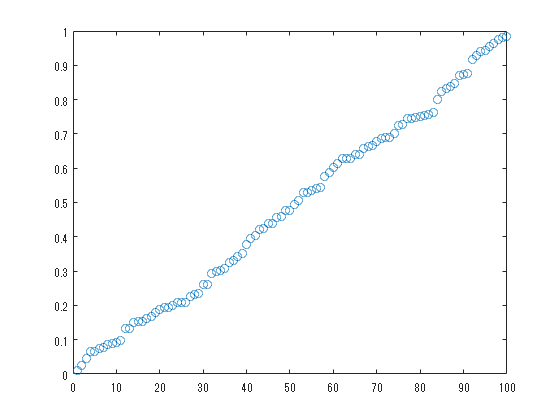

% 準位による表現
plot(sort(rand([100 1])), 'o')

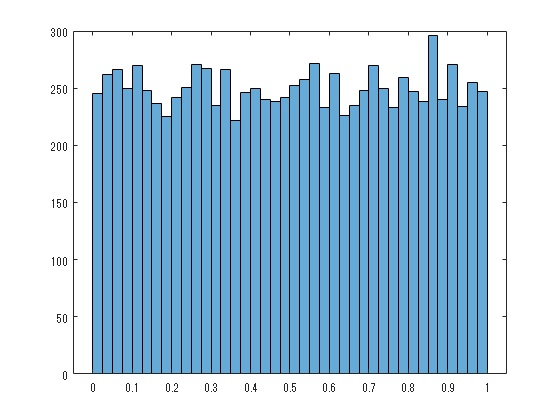

rd1 = rand([10000 1]);
histogram(rd1, 40);


format long g
disp(sum(rd1))

          5000.79508603148



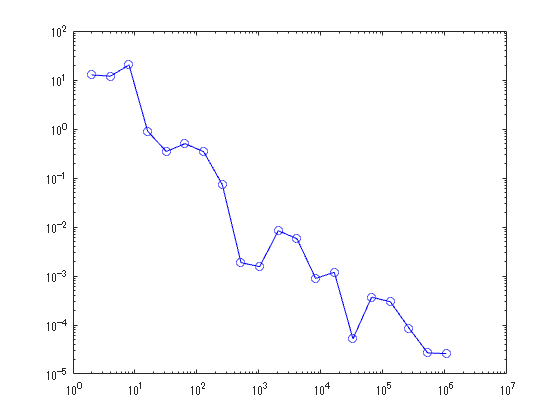

hb = 1:20;
h = histogram(rd1, 'Visible', 'off');
a = 0;
hold on
for n = hb
    h.NumBins = 2^n;
    s = sum(h.Values .* (h.BinEdges(1:end-1)+h.BinWidth/2));
    a(n) = abs(s-sum(rd1));
end

plot(2.^hb, a, 'bo-')
set(gca, 'YScale', 'log');
set(gca, 'XScale', 'log');
hold off

## 指数分布の場合

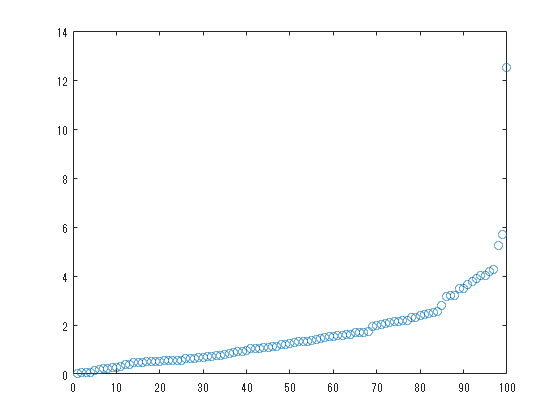

% 準位による表現
mu = 1.7;
pd2 = makedist("Exponential", mu);
plot(sort(random(pd2, [100 1])), 'o')

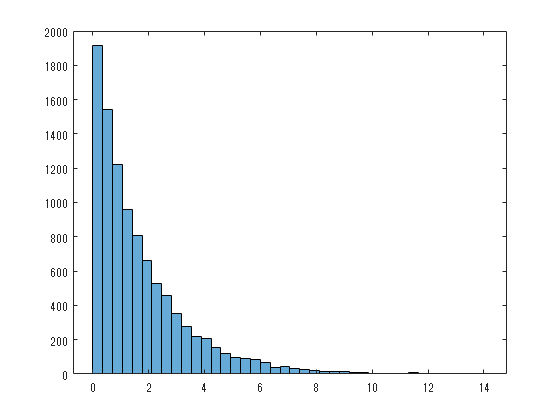


rd2 = random(pd2,[10000 1]);

histogram(rd2, 40);


format long g
disp(sum(rd2))

          17146.7162943933



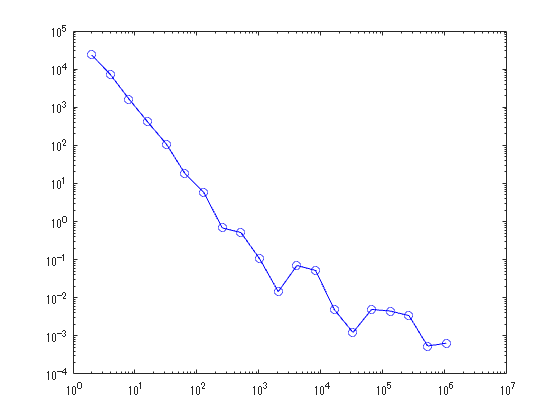

hb = 1:20;
h = histogram(rd2, 'Visible', 'off');
a = 0;
hold on
for n = hb
    h.NumBins = 2^n;
    s = sum(h.Values .* (h.BinEdges(1:end-1)+h.BinWidth/2));
    a(n) = abs(s-sum(rd2));
end

plot(2.^hb, a, 'bo-')
set(gca, 'YScale', 'log');
set(gca, 'XScale', 'log');
hold off

## Bose分布の場合（BEC）

% 準位による表現
mu = 1.7;
pd2 = makedist("Exponential", mu);
plot(sort(random(pd2, [100 1])), 'o')


rd2 = random(pd2,[10000 1]);

histogram(rd2, 40);

format long g
disp(sum(rd2))
hb = 1:20;
h = histogram(rd2, 'Visible', 'off');
a = 0;
hold on
for n = hb
    h.NumBins = 2^n;
    s = sum(h.Values .* (h.BinEdges(1:end-1)+h.BinWidth/2));
    a(n) = abs(s-sum(rd2));
end

plot(2.^hb, a, 'bo-')
set(gca, 'YScale', 'log');
set(gca, 'XScale', 'log');
hold off